This is mainly for the development of Gaussian kernel graphics for use within the thesis paper.

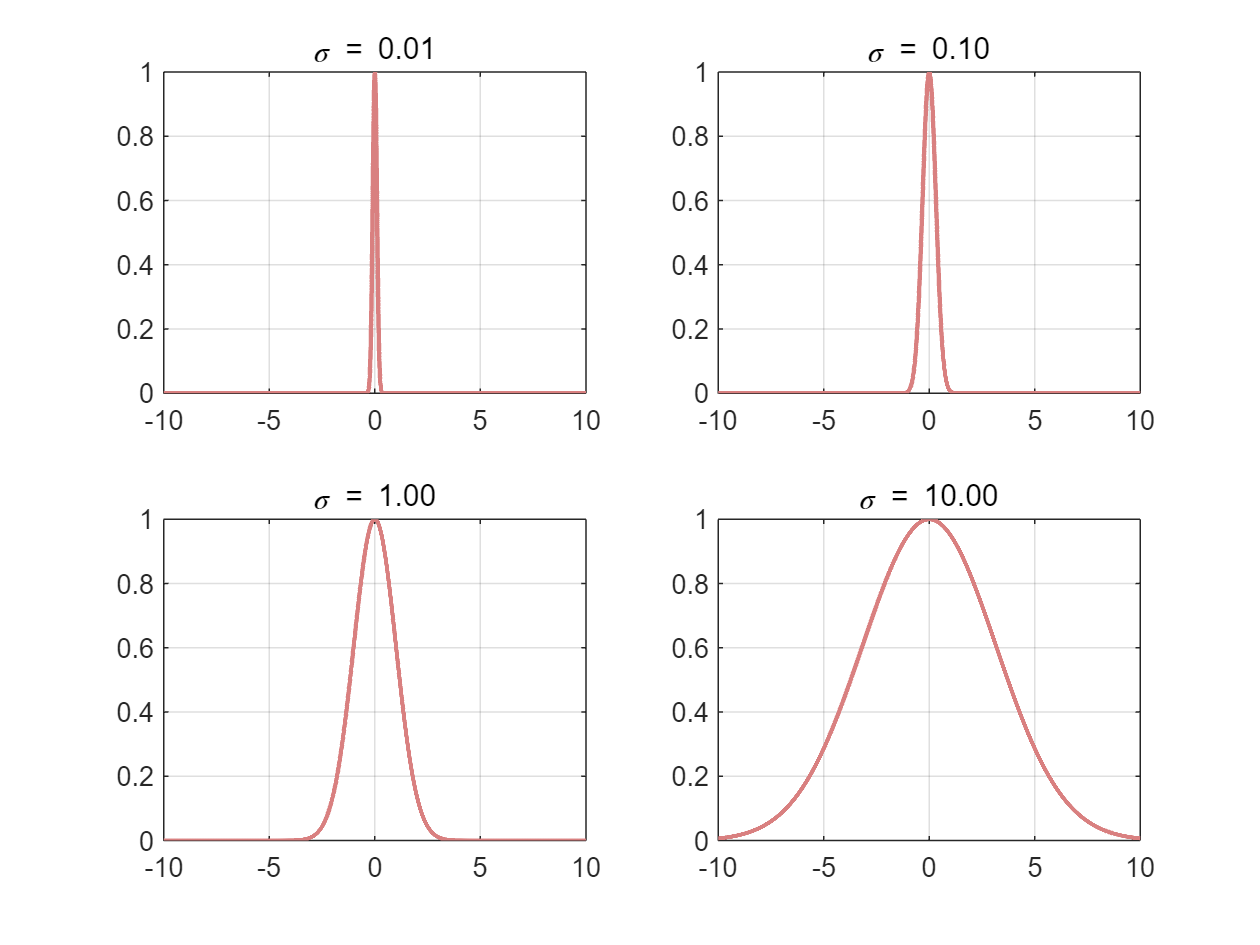

% --Setup
    clc; clear; format compact; close all;

% --Parameters
    step = 1000;
    sigma = [0.01, 0.1, 1, 10];
    x = -10:1/step:10;
    solution = [];

% --Calculate gaussian to show the spread of sigma
    for i = 1:length(sigma)
        
        k = exp( -(x.^2) ./ (2*sigma(i)) );
        
        subplot(2,2,i)
        plot(x,k,'LineWidth',1.5,'Color',[0.85 0.5 0.5])
            grid on
            hold on
            str = sprintf("\\sigma = %2.2f", sigma(i));
            subtitle(str)

    end

## Computing a 3D model of the Kernel

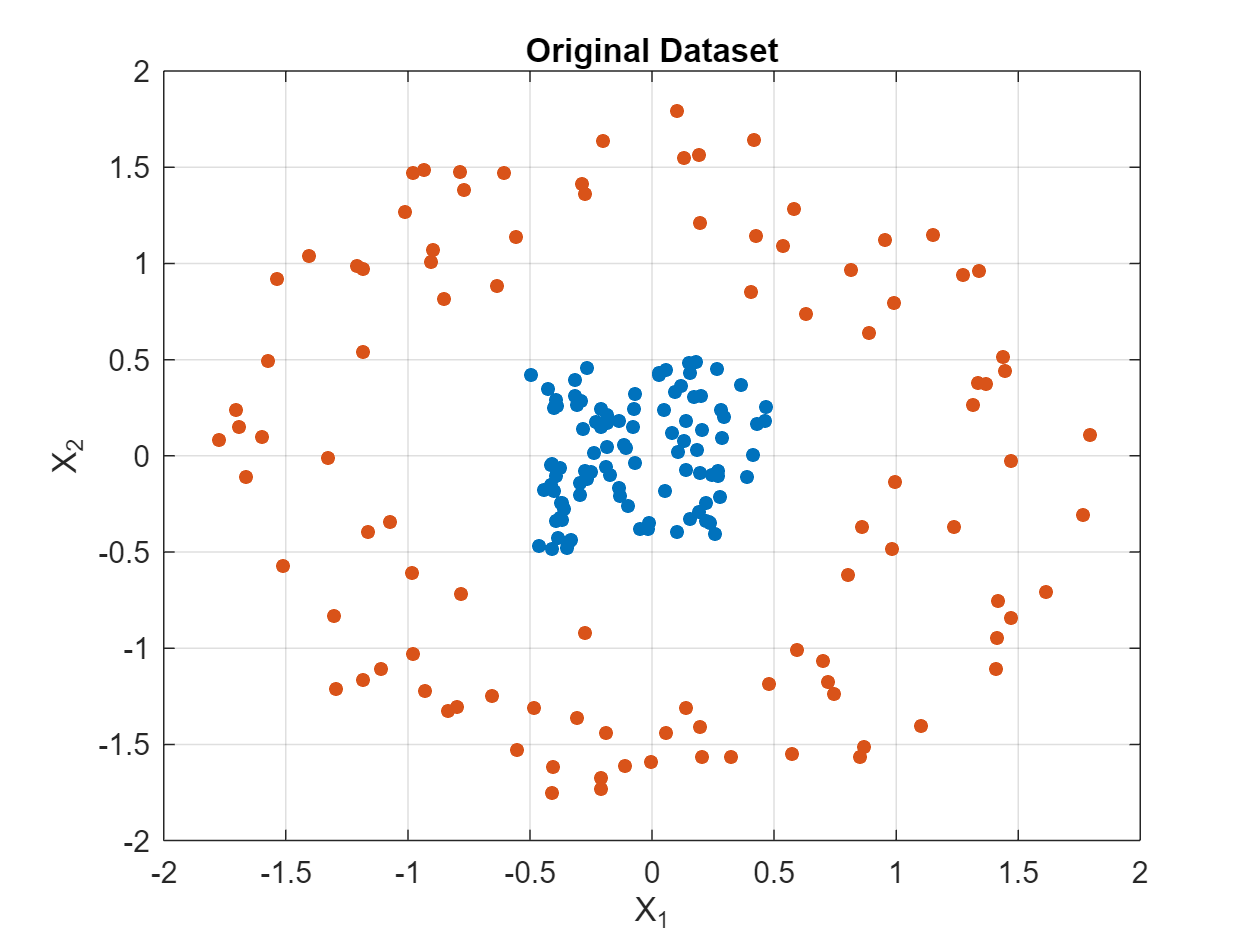

% --Setup
    step = 100;
    sigma = 0.1;
    x = -2:1/step:2;
    values_x = rand([1, 100]) - 0.5;
    values_y = rand([1,100]) - 0.5;

    r = 0.8 + sqrt(rand([1,100]));
    theta = rand([1,100]) .* 2 .* pi;

    values_x_2 = r.*cos(theta);
    values_y_2 = r.*sin(theta);

% --Plot original set
    figure()
    plot(values_x,values_y,'.', 'MarkerSize',14)
        hold on
        grid on
        xlim([-2 2])
        ylim([-2 2])

    plot(values_x_2, values_y_2, '.', 'MarkerSize', 14)
        title('Original Dataset')
        xlabel('X_1')
        ylabel('X_2')

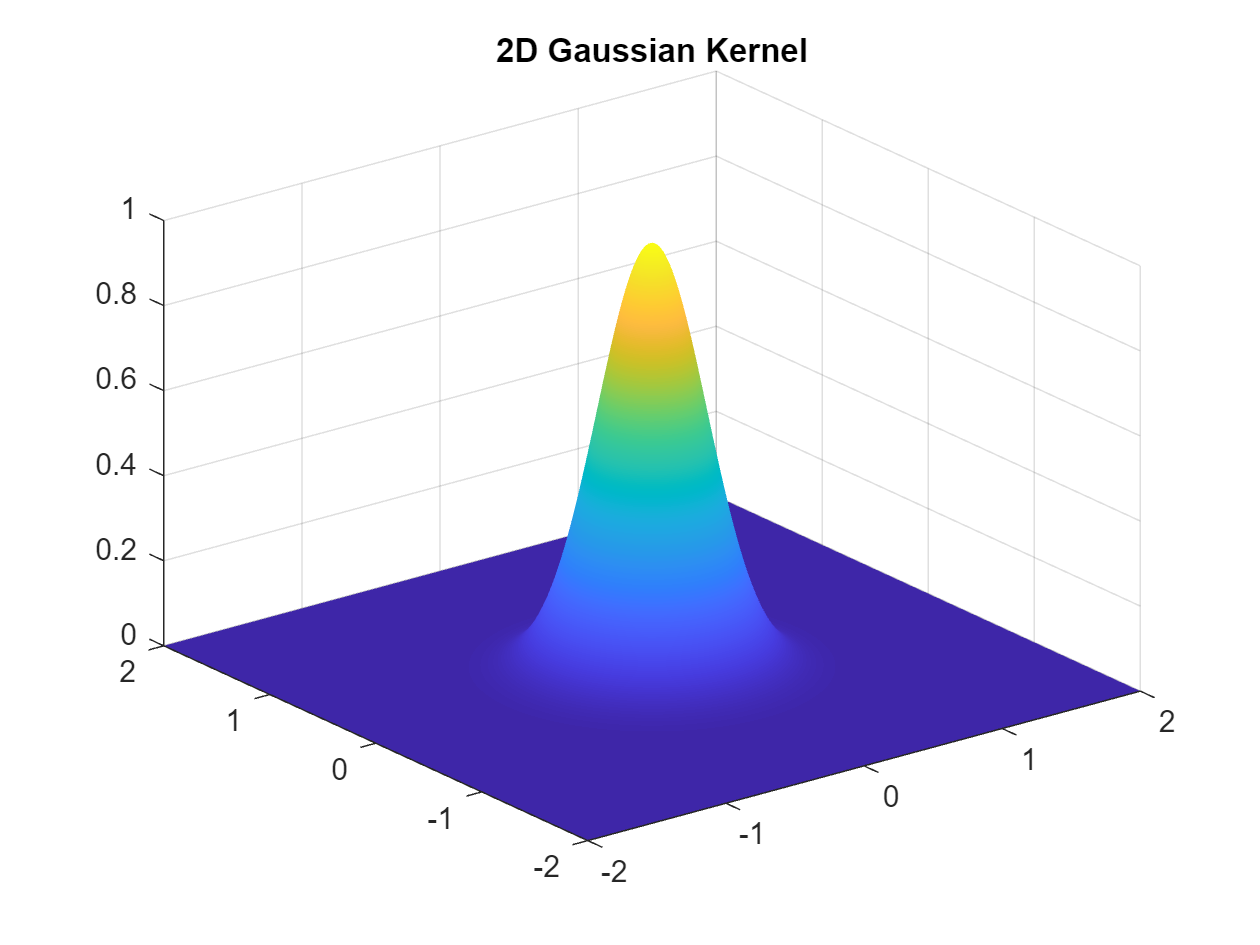


% --Calculating kernel
    [X,Y]=meshgrid(x,x);
    k = exp(-(X.^2 + Y.^2) ./ (2*sigma));
    figure()
    surf(X,Y,k)
    shading interp
    title('2D Gaussian Kernel')

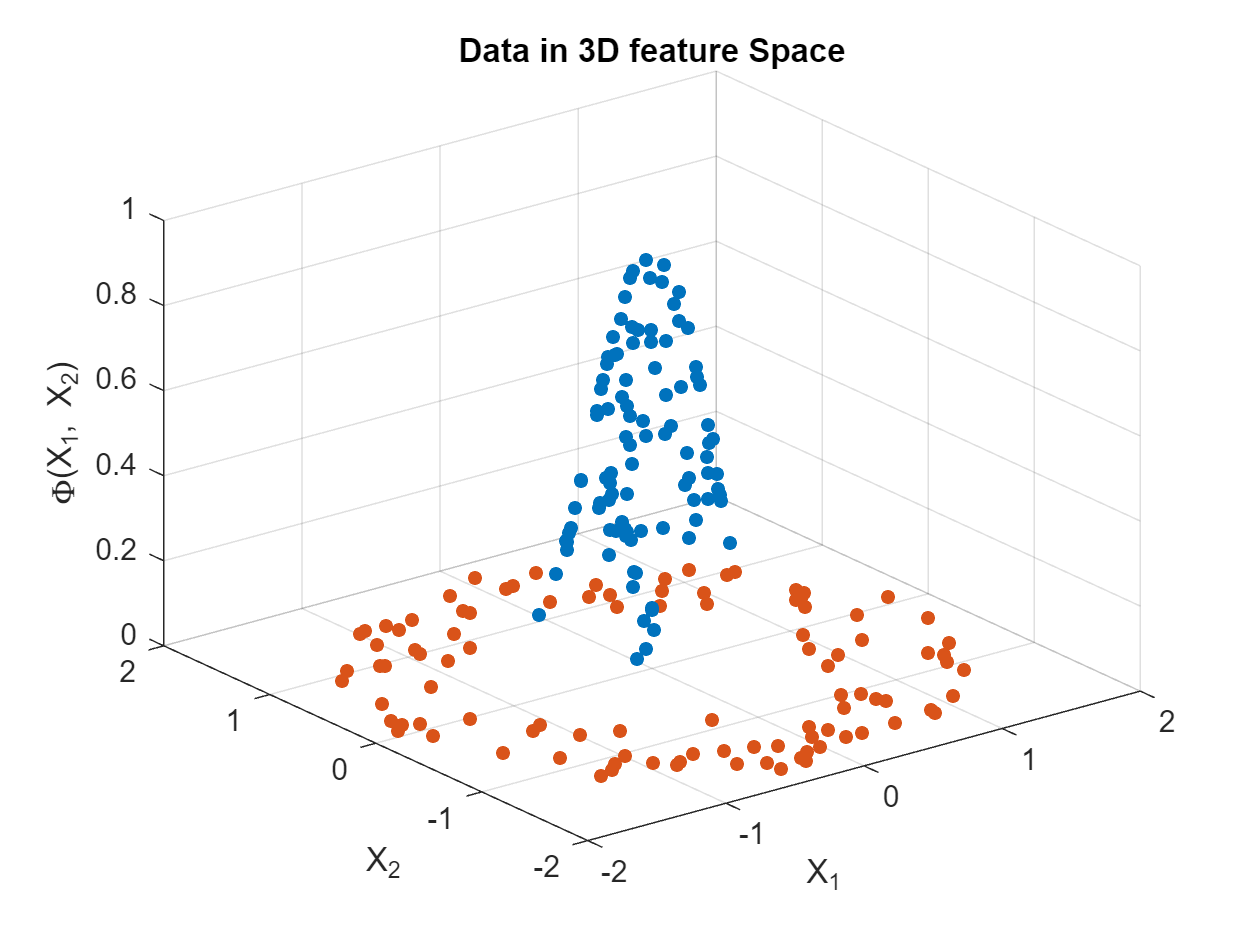


% --Calculating projection of datasets
    X = [values_x];
    Y = [values_y];
    k = exp(-(X.^2 + Y.^2) ./ (2*sigma));

    X2 = [values_x_2];
    Y2 = [values_y_2];
    k2 = exp(-(X2.^2 + Y2.^2) ./ (2*sigma));

% --Plot Projection
    figure()
    plot3(X,Y,k,'.','MarkerSize', 14)
        hold on
        grid on

    plot3(X2,Y2,k2,'.','MarkerSize', 14)
    title('Data in 3D feature Space')
    xlabel('X_1')
    ylabel('X_2')
    zlabel('\Phi(X_1, X_2)')

## Optimized Kernel Graphs

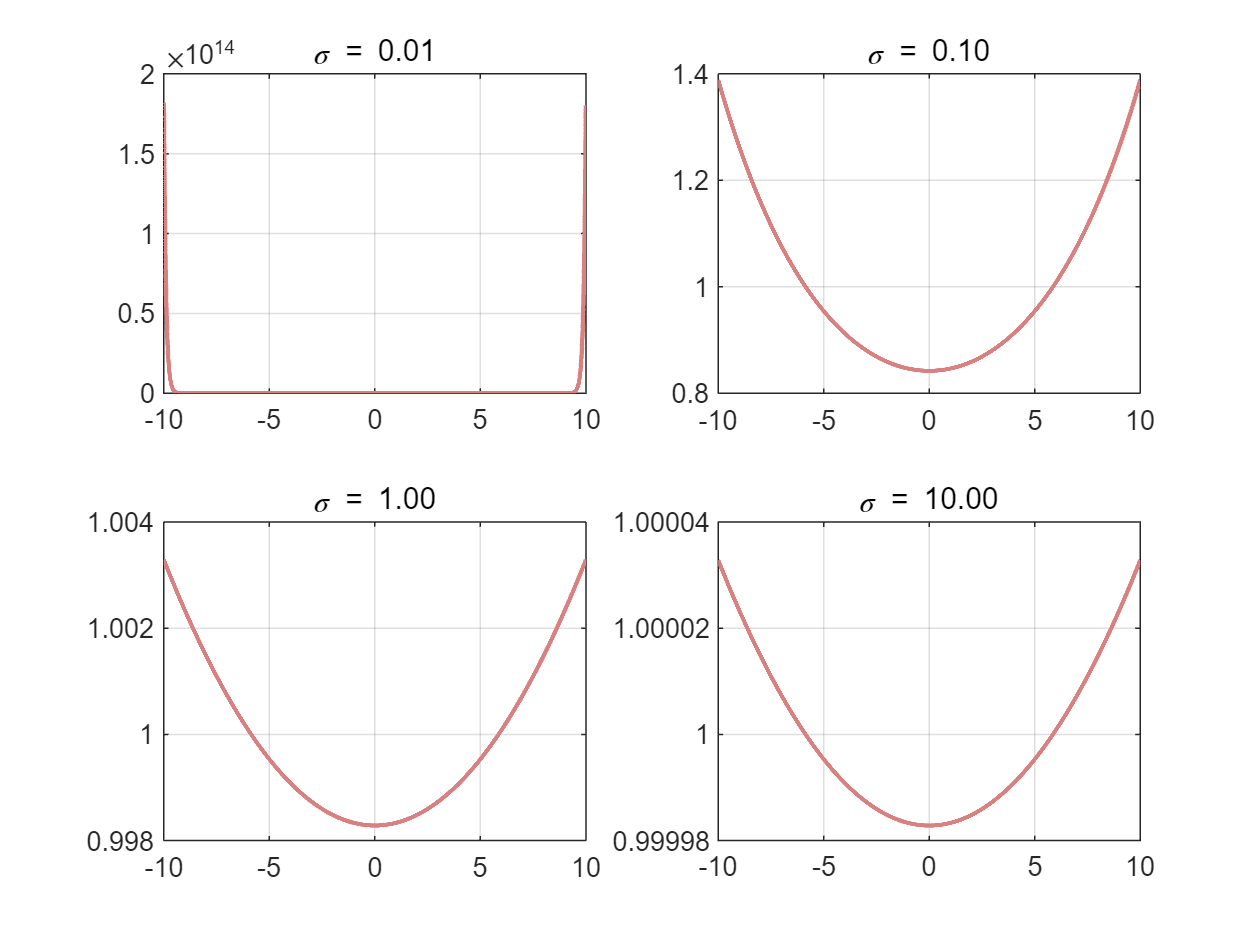

% --Setup
    close all;

% --Parameters
    step = 1000;
    sigma = [0.01, 0.1, 1, 10];
    x = -10:1/step:10;
    solution = [];

% --Calculating optimized kernel
    fx = abs(fft(x));
    xx = ifft(fx .* conj(fx)) ./ length(fx);
    N = length(xx);

% --Calculate gaussian to show the spread of sigma
    for i = 1:length(sigma)
        
        k = exp(-1 / sigma(i)^2 * (1 - 2 * xx) / N);
        
        subplot(2,2,i)
        plot(x,k,'LineWidth',1.5,'Color',[0.85 0.5 0.5])
            grid on
            hold on
            str = sprintf("\\sigma = %2.2f", sigma(i));
            subtitle(str)

    end


% --